clc; clear all; close all;
rng default % for reproducibility

Load audio files

[boy, sr_b] = audioread('man.wav'); %fs_b: sampling rate
[girl, sr_g] = audioread('girl.wav'); %fs_b: sampling rate

n = min(length(boy), length(girl));
boy = boy(1:n);
girl = girl(1:n);

sr_b

sr_b = 16000

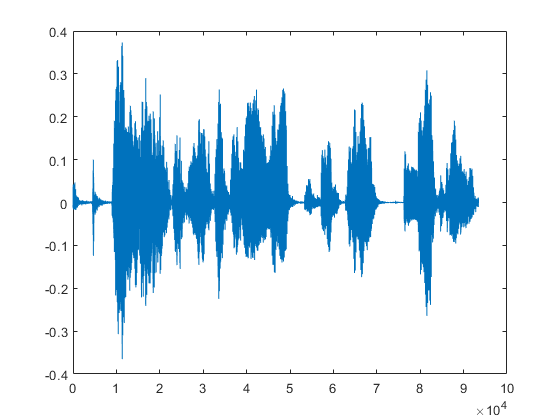


figure(1);
plot(boy);

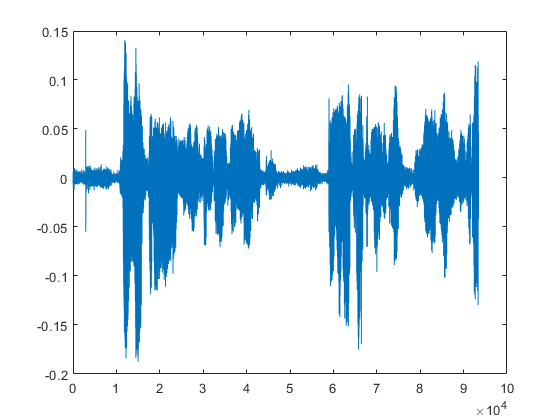

sound(boy, sr_b);

pause(5);

figure(2);
plot(girl);

sound(girl, sr_g);

Applying FFT to full signal. (for boy)

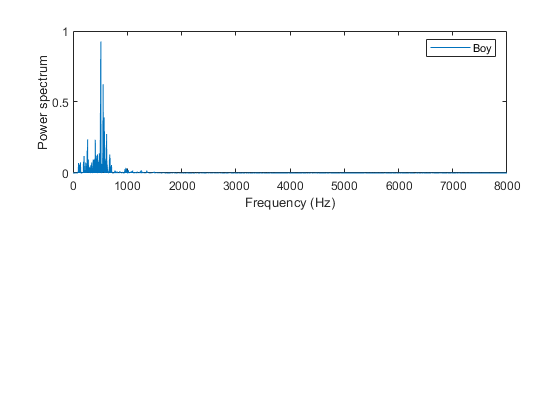

fs_boy = fft(boy, n); %applying fft
psd_boy = fs_boy.*conj(fs_boy)/n;
dt = 1/sr_b;
ws = 1/(dt*n)*(0:n);
L = 1:floor(n/2);

figure(3);
subplot(2, 1, 1);
plot(ws(L), psd_boy(L));
legend('Boy')
ylabel('Power spectrum');
xlabel('Frequency (Hz)');

Applying FFT to full signal. (for girl)

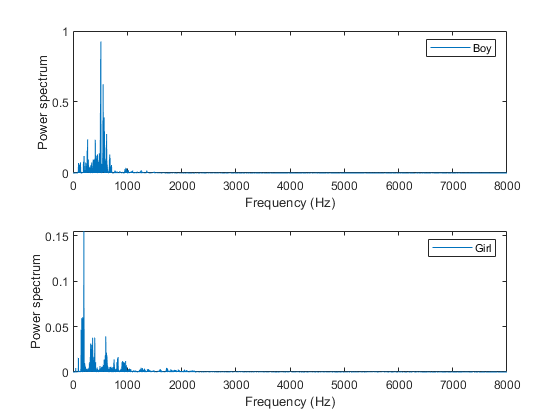

fs_girl = fft(girl, n);
psd_girl = fs_girl.*conj(fs_girl)/n;
dt = 1/sr_g;
ws = 1/(dt*n)*(0:n);
L = 1:floor(n/2);
subplot(2, 1, 2);
plot(ws(L), psd_girl(L));
legend('Girl')
ylabel('Power spectrum');
xlabel('Frequency (Hz)');

Spectrum with sample example (from Matlab site)

정현파 간의 합으로 구성된 신호의 개(?) 샘플을 생성

정현파의 정규화 주파수는 rad/sample 및 rad/sample.

더 높은 주파수를 가진 정현파의 진폭은 상대 정현파 진폭의 10배

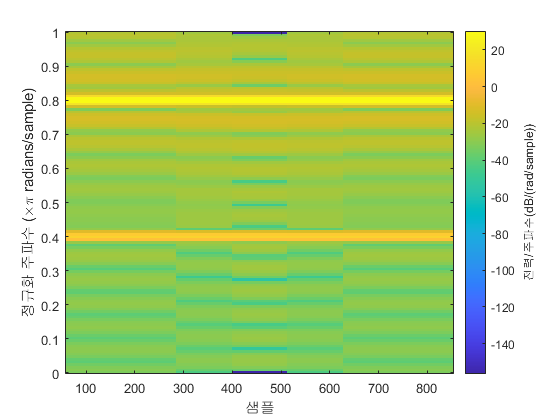

N2 = 1024;
n2 = 0:N2-1;

w0 = 2*pi/5;
x = sin(w0*n2)+10*sin(2*w0*n2);

s = spectrogram(x);
figure(4);
spectrogram(x, 'yaxis')

Spectrogram using STFT (Short Time Frourier Transform) (이 부분 = 딥러닝 인풋)

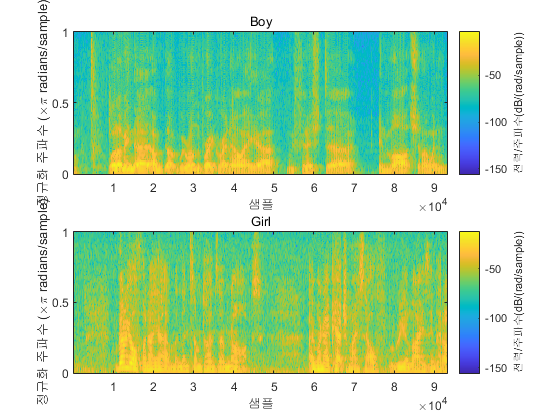

window_size = 2^7;
figure(5)
subplot(2, 1, 1);
spectrogram_boy = spectrogram(boy, window_size);
spectrogram(boy, window_size, 'yaxis')
title('Boy')
subplot(2, 1, 2);
spectrogram_girl = spectrogram(boy, window_size);
spectrogram(girl, window_size, 'yaxis')
title('Girl')

Pitch: the fundamental frequency over time for the audio inptu (Boy)

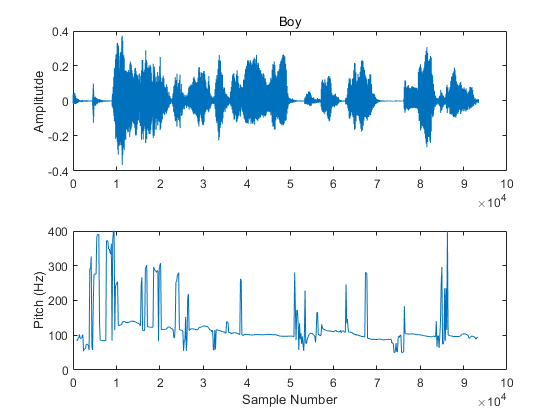

[pitch_boy, pitch_loc_boy] = pitch(boy, sr_b);
figure(6);
subplot(2, 1, 1)
plot(boy)
ylabel('Amplitutde')
title('Boy')

subplot(2, 1, 2)
plot(pitch_loc_boy, pitch_boy)
ylabel('Pitch (Hz)')
xlabel('Sample Number')

Pitch: the fundamental frequency over time for the audio input (Girl)

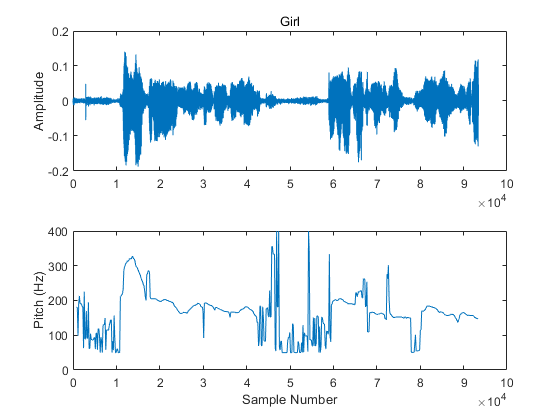

[pitch_girl, pitch_loc_girl] = pitch(girl, sr_g);

figure(7);
subplot(2, 1, 1)
plot(girl)
ylabel('Amplitude')
title('Girl')

subplot(2, 1, 2)
plot(pitch_loc_girl, pitch_girl)
ylabel('Pitch (Hz)')
xlabel('Sample Number')

Specify pitch detection using a 50ms window legnth and 40 ms overlap(10ms hop). Specify that the pitch function saeches for the fundamental frequency over the range 50-250 Hz and postprocesses the results with a median filter. Plot the results.

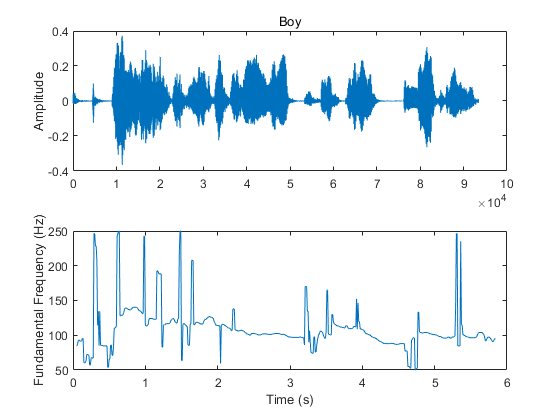

windowLength = round(0.05 * sr_b);
overlapLength = round(0.04 * sr_b);
hopLength = windowLength - overlapLength;

[f_b, loc_b] = pitch(boy, sr_b, ...
    'WindowLength', windowLength, ...
    'OverlapLength', overlapLength, ...
    'Range',[50 250], ...
    'MedianFilterLength', 3);

figure(8);
subplot(2, 1, 1);
plot(boy)
ylabel('Amplitude');
title('Boy')

subplot(2, 1, 2);
plot(loc_b/sr_b, f_b)
ylabel('Fundamental Frequency (Hz)')
xlabel('Time (s)')


windowLength = round(0.05*sr_g)

windowLength = 800

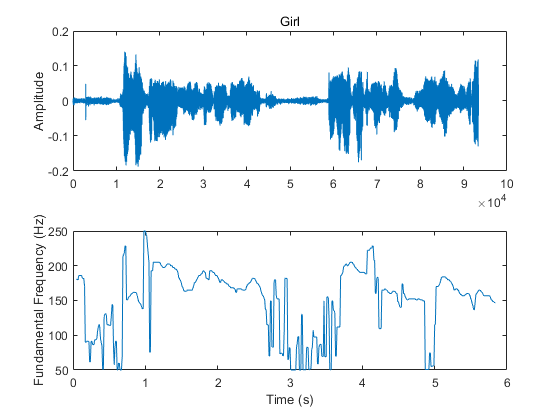

overlapLength = round(0.04*sr_g);
hopLength = windowLength - overlapLength;

[f_g, loc_g] = pitch(girl, sr_g, ...
    'WindowLength', windowLength, ...
    'OverlapLength', overlapLength, ...
    'Range',[50 250], ...
    'MedianFilterLength', 3);

figure(9);
subplot(2, 1, 1);
plot(girl)
ylabel('Amplitude');
title('Girl')

subplot(2, 1, 2);
plot(loc_g/sr_g, f_g)
ylabel('Fundamental Frequency (Hz)')
xlabel('Time (s)')

Compariosn of pitch histogram of boy and girl

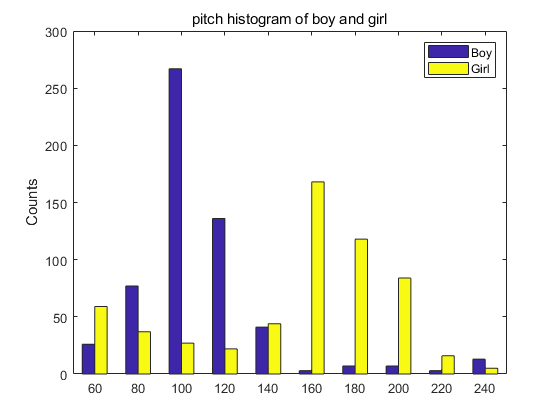

figure(10);
hist([f_b, f_g])
ylabel('Counts')
legend('Boy', 'Girl')
title('pitch histogram of boy and girl')

MFCC for audio signals

MFCC (Mel frequency cepstral coefficients)

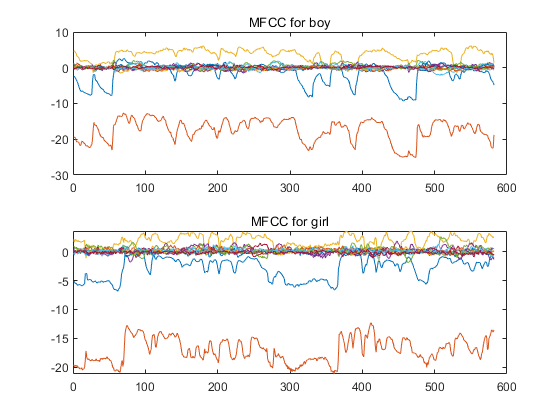

mfcc_boy = mfcc(boy, sr_b);
mfcc_girl = mfcc(girl, sr_g);
figure(11);
subplot(2, 1, 1);
plot(mfcc_boy);
title('MFCC for boy')
subplot(2, 1, 2);
plot(mfcc_girl)
title('MFCC for girl')

DCT (Discret COsine Transform)

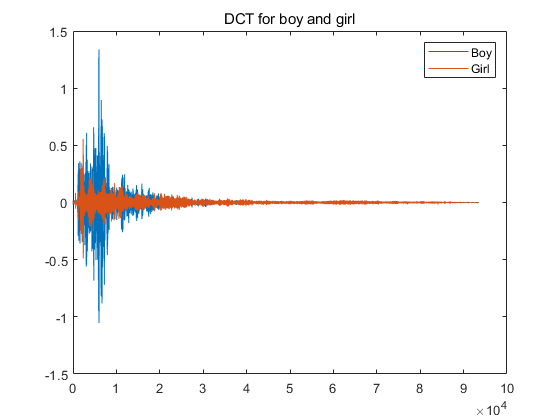

fs_dct_boy = dct(boy);
fs_dct_girl = dct(girl);
figure(12);
plot([fs_dct_boy, fs_dct_girl]);
legend('Boy', 'Girl');
title('DCT for boy and girl')

Signal Convert (Combine) - combine boy and girl signals (포렌식 관점에서 다른 두 개파일이 붙어 있는 것을 확인)

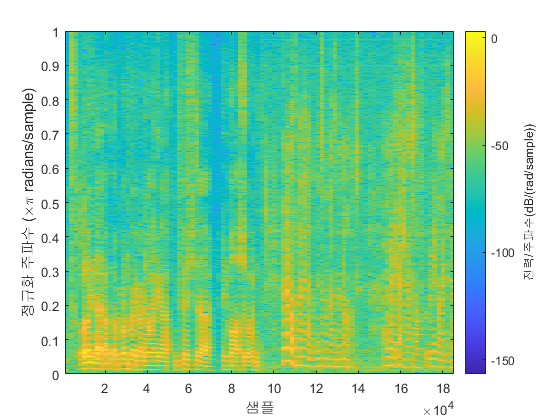

CombinedSignal = [boy', girl'];

window_size = 2^12;
spectrogram(CombinedSignal, window_size, 'yaxis');

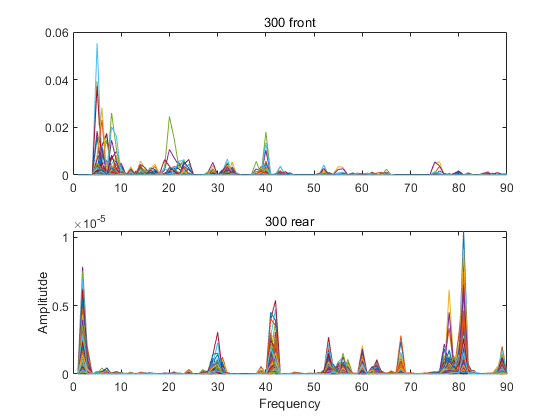

spec_combined = spectrogram(CombinedSignal, window_size, 'yaxis');

power_spectrum_combined = spec_combined.*conj(spec_combined)/length(CombinedSignal);

A = power_spectrum_combined(1:300, :);
B = power_spectrum_combined(1501:1800, :);
gender = cell(600, 1);
for i=1:600,
    if i<=300
        gender{i} = "Boy";
    else
        gender{i} = "Girl";
    end
end

figure(15);
subplot(2, 1, 1)
plot(A');
title('300 front')
subplot(2, 1, 2)
plot(B');
title('300 rear')
xlabel('Frequency')
ylabel('Amplitutde')

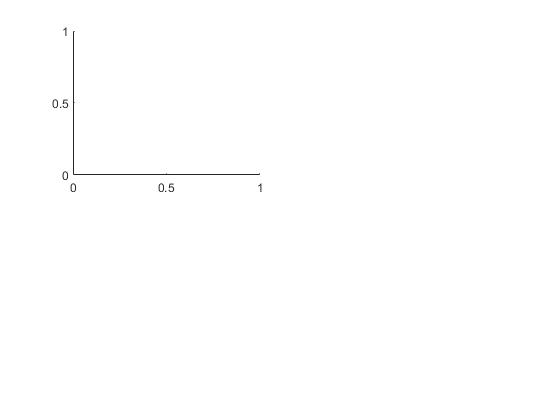

다음 사용 중 오류가 발생함: statslib.internal.grp2idx (line 99)
그룹화 변수는 categorical형 벡터, 숫자형 벡터, 논리형 벡터, datetime형 벡터, duration형 벡터, 문자형 배열, string형 배열 또는 문자형 벡터로 구성된 셀형 벡터여야 합니다.

오류 발생: statslib.internal.mgrp2idx (line 35)
    [ogroup,gname] = statslib.internal.grp2idx(group);

오류 발생: 


Data = [A; B];

Y = tsne(Data, 'Algorithm', 'exact', 'Distance', 'mahalanobis');
figure(16);
subplot(2, 2, 1)
gscatter(Y(:,1), Y(:,2), gender)

title('Mahalanobis')

rng('default') % for fair comparison
Y = tsne(Data, 'Algorithm', 'exact', 'Distance', 'cosine');
subplot(2, 2, 2)
gscatter(Y(:,1), Y(:,2), gender)
title('Cosine')

rng('default') % for fair comparison
Y = tsne(Data, 'Algorithm', 'exact', 'Distance', 'chebychev');
subplot(2, 2, 3)
gscatter(Y(:,1), Y(:,2), gender)
title('Chebychev')

rng('default') % for fair comparison
Y = tsne(Data, 'Algorithm', 'exact', 'Distance', 'euclidean');
subplot(2, 2, 4)
gscatter(Y(:,1), Y(:,2), gender)
title("Euclidean")

Signal Convert (Combine) - t-SNE for fully combined signals

CombinedSignal = [boy', girl'];

window_size = 2^12;
spectrogram(CombinedSignal, window_size, 'yaxis');

spec_combined = spectrogram(CombinedSignal, window_size, 'yaxis');

power_spectrum_combined = spec_combined.*conj(spec_combined)/length(CombinedSignal);

Data = power_spectrum_combined;

rng('deafult') % for fair comparison

다음 사용 중 오류가 발생함: rng (line 130)
첫 번째 입력값은 다음 중 하나여야 합니다. 2^32보다 작은 음이 아닌 정수 시드(seed), 'shuffle', 'default', S = RNG를 사용하여 이전에 캡처한 생성기 설정.

Y = tsne(Data, 'Algorithm','exact','Distance','cosine');
figure(17);
gscatter(Y(:,1), Y(:,2))
title('Signal Convert (Combine) - Cosine')

AudioFile Converting: File Split and Merge

boy1 = boy(1:round(length(boy)/3));
boy2 = boy(round(length(boy)/3)+1 :round(length(boy)/3*2));
boy3 = boy(round(length(boy)/3*2)+1:end);

[length(boy1), length(boy3)]

ans =        31147       31147


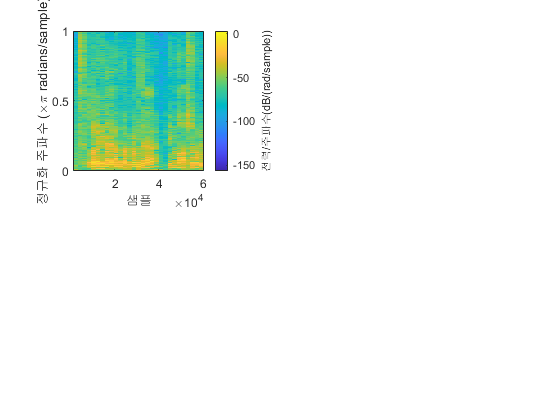


window_size = 2^12;

original_voice = boy(1:length([boy1; boy3]));
spectrogram(original_voice, window_size, 'yaxis');
spec_combined = spectrogram(original_voice, window_size, 'yaxis');
Original_Data = spec_combined.*conj(spec_combined)/length(original_voice);
Difference_OD = sum((Original_Data(:,1:end-1)-Original_Data(:,2:end)).^2,1);

distorted_voice = [boy1; boy3]; % Missing boy2

spectrogram(distorted_voice, window_size, 'yaxis');

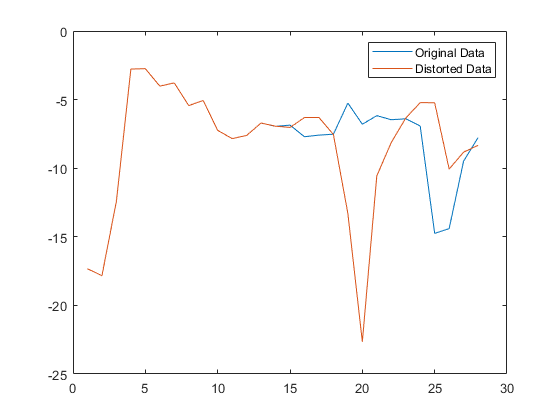

spec_combined = spectrogram(distorted_voice, window_size, 'yaxis');
Distorted_Data = spec_combined.*conj(spec_combined)/length(distorted_voice);
Difference_DD = sum((Distorted_Data(:, 1:end-1)-Distorted_Data(:, 2:end)).^2, 1);

figure(18); clf;
plot(log([Difference_OD', Difference_DD']))
legend('Original Data', 'Distorted Data')